# Covid classification - CRNN

remove previous data

close all; clc; clear;

Create audioDatastore objects of the data and split it into train, validation and test sets

dataset_name = "all"; % choose dataset
shuffle_dataset = "no"; % choose if to shuffle the datasets

% load data
[adsTrain, adsVal, adsTest] = load_datasets_train_val_test(shuffle_dataset, dataset_name);

choose hyper-parameters

% win & spectrogram length/overlap info
win_info.win_len = 128;
win_info.overlap_coeff_win = 0.5;
win_info.overlap_coeff_spectrograms = 0.75;

% win & spectrogram normalization info
SpectrumType = "power"; % "power" "magnitude"
WindowNormalization = false; % true false
FilterBankNormalization = "none"; % "area" "bandwidth" "none"

% LSTM
numHiddenUnits = 512;
drop_prob = 0.1; % 0.05 0.1 0.15 0.2 0.25

MaxEpochs = 30;
miniBatchSize = 4;
InitialLearnRate = 0.0001;
L2Regularization = 0.003;
LearnRateSchedule = "piecewise"; % "none" "piecewise"
LearnRateDropPeriod = 1; % 1 2
LearnRateDropFactor = 0.7;
ValidationPatience = 5;
SequencePaddingDirection = "right"; % "right" "left"
SequenceLength = "longest"; % "longest" (default) | "shortest" | positive integer

win_info = extrct_win_info(win_info);

afe = audioFeatureExtractor(...
    'SampleRate',       win_info.fs, ...
    'Window',           win_info.win, ...
    'OverlapLength',    win_info.numSamplesOverlapBetweenWin, ...
    'melSpectrum',      true ...
    );

setExtractorParams( ...
    afe,                        'melSpectrum', ...
    'SpectrumType',             SpectrumType, ... % 'power' (default) | 'magnitude'
    'NumBands',                 win_info.num_bands, ...
    "WindowNormalization",      WindowNormalization, ... % true (default) | false
    'FilterBankNormalization',  FilterBankNormalization ... % 'bandwidth' (default) | 'area' | 'none'
    );

preprocess datasets: extract auto-segmentation results from yamnet model

% pre-processing - cough event indices
[FeaturesTrain, trueLabelsTrain, adsSpecsTrain] = preprocess_classification_CRNN(adsTrain, win_info, afe);
[FeaturesVal, trueLabelsVal, adsSpecsVal] = preprocess_classification_CRNN(adsVal, win_info, afe);
[FeaturesTest, trueLabelsTest, adsSpecsTest] = preprocess_classification_CRNN(adsTest, win_info, afe);

Sort Sequences by Length

% sequenceLengths = cellfun(@(X) size(X,4), FeaturesTrain);
% [sequenceLengthsSorted, idx] = sort(sequenceLengths);
% FeaturesTrain = FeaturesTrain(idx);
% trueLabelsTrain = trueLabelsTrain(idx);
% 
% % Truncate Sequences: reduce length of sequences to max size
% max_seq_len = 80;
% idxSorted = 1 : length(sequenceLengthsSorted);
% idx_above_th = idxSorted(sequenceLengthsSorted > max_seq_len);
% for subj_indx = idx_above_th
%     sequence = FeaturesTrain{subj_indx, 1};
%     sequence = sequence(:,:,:, 1 : max_seq_len);
%     FeaturesTrain{subj_indx, 1} = sequence;
% end

set classes and classes weights

uniqueLabels = unique(trueLabelsTrain);
numLabels = 2;
num_train_pos = sum(trueLabelsTrain == "positive");
num_train_neg = sum(trueLabelsTrain == "negative");
num_train = num_train_pos + num_train_neg;
classWeightsUniform = 'none';
classWeightsNonUniform = [num_train_pos, num_train_neg] / num_train;

classWeights = classWeightsNonUniform;

load CNN network

net_name = "vggish";
net_cnn = load_cnn_layers(net_name);

load VGGish neural network for features embedding

downloadFolder = fullfile(tempdir,'VGGishDownload');
loc = websave(downloadFolder,'https://ssd.mathworks.com/supportfiles/audio/vggish.zip');
VGGishLocation = tempdir;
unzip(loc,VGGishLocation);
addpath(fullfile(VGGishLocation,'vggish'));
net_vggish = vggish;
% analyzeNetwork(net_vggish);

create LSTM network

numFeatures = net_vggish.Layers(22, 1).OutputSize; % No. output features from CNN
numClasses = 2; % No. classes

lstmLayers = [
    bilstmLayer(numHiddenUnits, 'OutputMode', 'last', 'Name', 'bilstm')
    dropoutLayer(drop_prob, 'Name', 'drop')
    fullyConnectedLayer(numClasses, 'Name', 'fc')
    softmaxLayer('Name', 'softmax')
    classificationLayer("Name", "classification", "Classes", uniqueLabels, "ClassWeights", classWeights)
    ];

assemble CNN and LSTM networks

lstm input -> folding -> CNN -> unfolding -> lstm -> classification

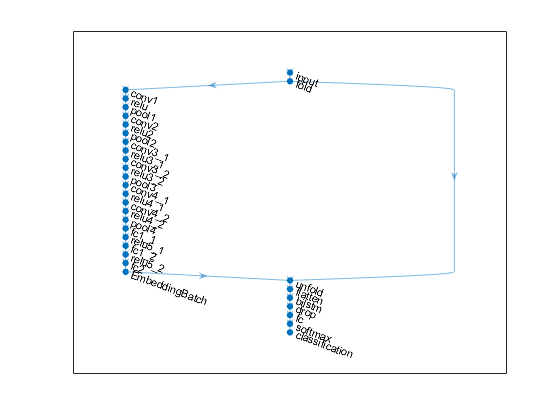

cnnLayers = layerGraph(net_vggish.Layers);

% remove layers from CNN: 1st (input) and last (regression)
layerNames = [string(net_vggish.Layers(1, 1).Name), string(net_vggish.Layers(24, 1).Name)];
cnnLayers = removeLayers(cnnLayers, layerNames);

% add new input layer (sequence input for lstm) and folding layer
inputSize = net_vggish.Layers(1).InputSize(1:2); % input size needs to be the same as for CNN
layers = [
    sequenceInputLayer([inputSize 1], 'Name', 'input') % sequence input for lstm
    sequenceFoldingLayer('Name', 'fold') % change structure for CNN
    ];

% connect new input layers to input of CNN
lgraph = addLayers(cnnLayers, layers);
lgraph = connectLayers(lgraph, "fold/out", string(net_vggish.Layers(2, 1).Name));

% add unfolding and lstm layers
layers = [
    sequenceUnfoldingLayer('Name', 'unfold') % change structure back for lstm
    flattenLayer('Name', 'flatten') % change dim from [1,1,128] to [128]
    lstmLayers
    ];

% connect unfolding and lstm layers to output of CNN
lgraph = addLayers(lgraph, layers);
lgraph = connectLayers(lgraph, string(net_vggish.Layers(23, 1).Name), "unfold/in");

% add parallel connection between folding & unfolding layers (needed to restore the sequence structure)
lgraph = connectLayers(lgraph, "fold/miniBatchSize", "unfold/miniBatchSize");

% analyze network
figure;
plot(lgraph);

% analyzeNetwork(lgraph);

specify training options

numObservations = numel(FeaturesTrain);
validationFrequency = floor(numObservations / miniBatchSize);

options = trainingOptions( ...
    'adam', ...
    'MaxEpochs', MaxEpochs, ...
    'MiniBatchSize', miniBatchSize, ...
    'Verbose', true, ... % 1 (true) (default) | 0 (false)
    'Shuffle', 'every-epoch', ... % 'once' (default) | 'never' | 'every-epoch'
    'ValidationData', {FeaturesVal, trueLabelsVal}, ...
    'ValidationFrequency', validationFrequency, ...
    'InitialLearnRate', InitialLearnRate, ...
    'LearnRateSchedule', 'piecewise', ... % piecewise, none
    'LearnRateDropPeriod', 1, ...
    'LearnRateDropFactor', LearnRateDropFactor, ...
    'L2Regularization', L2Regularization, ...
    'SequencePaddingDirection', SequencePaddingDirection, ...
    'SequenceLength', SequenceLength, ... % "longest" (default) | "shortest" | positive integer
    'ValidationPatience', ValidationPatience, ...
    'Plots', 'training-progress' ... % 'none' (default) | 'training-progress'
    );

Train the LSTM network with the specified training options.

net_classification_CRNN = trainNetwork(FeaturesTrain, trueLabelsTrain, lgraph, options);

predict on train, val and test sets (probability [0,1]).

miniBatchSize_predict = 1;
predLabelsTrain = predict(net_classification_CRNN, FeaturesTrain, 'MiniBatchSize', miniBatchSize_predict);
predLabelsTrain = predLabelsTrain(:, 2);
predLabelsVal   = predict(net_classification_CRNN, FeaturesVal, 'MiniBatchSize', miniBatchSize_predict);
predLabelsVal   = predLabelsVal(:, 2);
predLabelsTest  = predict(net_classification_CRNN, FeaturesTest, 'MiniBatchSize', miniBatchSize_predict);
predLabelsTest  = predLabelsTest(:, 2);

find best ROC thrshold on val set, and plot ROC curve

plot ROC curve and confusion matrix on test set.

display for train, val and test sets:

- ROC & AUC

- confusion matrix

- accuracy, UAR (unweighted average recall), F1 score, sensetivity, PPV, specificity

accuracy = (TP + TN) / (TP + TN + FP + FN)

UAR = (sensetivity + specificity) / 2

F1-score = 2 * (PPV * sensitivity) / (PPV + sensitivity)

sensitivity = TP / (TP + FN)

PPV = TP / (TP + FP)

specificity = TN / (TN + FP)

roc_threshold = 0.5; % choose threshold for ROC curve

extract_scores_classification_CRNN( ...
    {predLabelsTrain predLabelsVal predLabelsTest}, ...
    {trueLabelsTrain trueLabelsVal trueLabelsTest}, ...
    roc_threshold);

Unrecognized function or variable 'predLabelsTrain'.